clear, close, clc

rA_prime_rA =1

rA_prime_rA = 1


mu = astroConstants(13);
rA = 10000; % [km]
rA_prime = rA_prime_rA * rA;

if rA_prime_rA == 1/3
    x1 = 0.5;
elseif rA_prime_rA == 1
    x1 = 1;
else
    x1 = 3;
end

x = x1:0.01:10;
y = 1.1:0.02:10;
rB = rA.*x;
rB_prime = rA.*y;
[ rB, rB_prime ] = meshgrid( rB, rB_prime );
[ x, y ] = meshgrid( x , y );

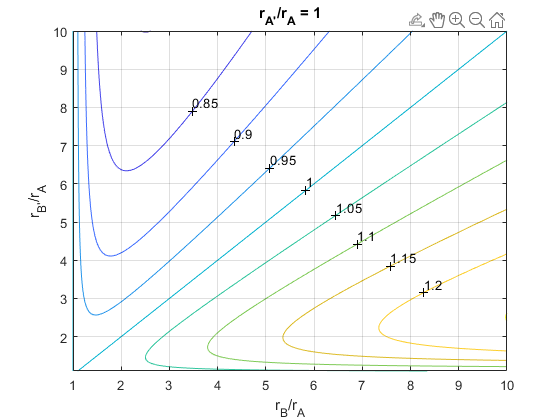

 
    Please wait a moment...
 
   Carefully select contours for labeling.
   When done, press RETURN while the Graph window is the active window.


% Ang. mom, velocities, total cost
h1 = sqrt(2*mu).*sqrt(rA.*rA_prime/(rA+rA_prime));
vA_1 = h1 / rA;
vA_prime_1 = h1 / rA_prime;

for i = 1:length(rB(:,1))
    for j = 1:length(rB(1,:))
        h2(i,j) = sqrt(2*mu).*sqrt(rB(i,j).*rB_prime(i,j)/(rB(i,j)+rB_prime(i,j)));
        h3(i,j) = sqrt(2*mu).*sqrt(rA.*rB(i,j)/(rA+rB(i,j)));
        h3_prime(i,j) = sqrt(2*mu)*sqrt(rA_prime*rB_prime(i,j)/(rA_prime+rB_prime(i,j)));
        vA_3(i,j) = h3(i,j) ./ rA;
        vB_2(i,j) = h2(i,j) ./ rB(i,j);
        vB_3(i,j) = h3(i,j) ./ rB(i,j);
        vA_prime_3_prime(i,j) = h3_prime(i,j) ./ rA_prime;
        vB_prime_2(i,j) = h2(i,j) ./ rB_prime(i,j);
        vB_prime_3_prime(i,j) = h3_prime(i,j) ./ rB_prime(i,j);
        deltaV_A(i,j) = abs(vA_3(i,j) - vA_1);
        deltaV_B(i,j) = abs(vB_2(i,j) - vB_3(i,j));
        deltaV_A_prime(i,j) = abs(vA_prime_3_prime(i,j) - vA_prime_1);
        deltaV_B_prime(i,j) = abs(vB_prime_2(i,j) - vB_prime_3_prime(i,j));
        deltaV3_tot(i,j) = deltaV_A(i,j) + deltaV_B(i,j);
        deltaV3_prime_tot(i,j) = deltaV_A_prime(i,j) + deltaV_B_prime(i,j);
        dV3p_dV3(i,j) = deltaV3_prime_tot(i,j)./deltaV3_tot(i,j);
    end
end

figure
[C,h] = contour(x,y,dV3p_dV3);
grid on
title(['r_{A''}/r_A = ', num2str(rA_prime_rA)]);
xlabel('r_B/r_A')
ylabel('r_{B''}/r_A')
clabel(C,['manual' ...
    ''])